# 二维截面计算：（重心、浮心、倾覆力矩，水线逼近）

tic;
clear all;
clc


## 船体数据导入：

- 经过点云截取获取的船体坐标点，这里截取平面进行分析

%经过点云截取获取的船体坐标点
Coord=load("point.m");%导入坐标点数据

x_axis=Coord(:,1)*0.001;%x,y,z轴
y_axis=Coord(:,2)*0.001;
z_axis=Coord(:,3)*0.001;

max_temp_Deepth=max(z_axis)

max_temp_Deepth = 0.0300

min_temp_Deepth=min(z_axis)

min_temp_Deepth = -0.1040

- 基本船体参数定义：


boat.L = 0.456        

boat = 包含以下字段的 struct :
    L: 0.4560


boat.W = max(y_axis)-min(y_axis);        
boat.HB = boat.W / 2;  % half breadth in 
boat.D = max(z_axis)-min(z_axis);        

boat.mass = 3.5;       % kg

max_area = boat.D * boat.W

max_area = 0.0279

max_volume = max_area * boat.L 

max_volume = 0.0127

density_water = 1025;    % kg / m^3
max_mass = max_volume * density_water

max_mass = 13.0274


%微分步长
dy = 0.001;   % meters
dz = 0.001;   % meters

mesh.ys = -boat.HB:dy:boat.HB;        % meters将截面沿y方向微分
mesh.zsp= 0:dz:boat.D;                % meters将截面沿z方向微分
mesh.zs =-1*mesh.zsp;                 % 正负转换

[mesh.ygrid,mesh.zgrid] = meshgrid(mesh.ys,mesh.zs); %返回网格坐标的副本，生成两个坐标矩阵
% mesh.ygrid每个元素对应船体截面该位置的y坐标值
% mesh.zgrid每个元素对应船体截面该位置的z坐标值

total_area = boat.W * boat.D       % m^2截面总面积

total_area = 0.0279

mesh.dA = total_area / numel(mesh.ygrid);
%numel(mesh.ygrid)求坐标矩阵的元素数目
%mesh.dA得到每个坐标点上的面积,用于后面船体截面计算


### 这里函数拟合大家可以使用cftool：

y = mesh.ys;

       p1 =   1.533e+05 

p1 = 153300

       p2 =      -627.7 

p2 = -627.7000

       p3 =       -2172 

p3 = -2172

       p4 =       9.788 

p4 = 9.7880

       p5 =       14.62 

p5 = 14.6200

       p6 =    -0.02439 

p6 = -0.0244

       p7 =    -0.09962 

p7 = -0.0996

z = p1*y.^6 + p2*y.^5 + p3*y.^4 + p4*y.^3 + p5*y.^2 + p6*y + p7       

z =    -0.0024   -0.0068   -0.0109   -0.0148   -0.0184   -0.0218   -0.0249   -0.0278   -0.0306   -0.0331   -0.0355   -0.0377   -0.0398   -0.0417   -0.0435   -0.0451   -0.0467   -0.0481   -0.0495   -0.0507   -0.0519   -0.0530   -0.0540   -0.0549   -0.0558   -0.0567   -0.0575   -0.0582   -0.0589   -0.0596   -0.0603   -0.0609   -0.0615   -0.0621   -0.0627   -0.0633   -0.0638   -0.0644   -0.0649   -0.0654   -0.0660   -0.0665   -0.0671   -0.0676   -0.0681   -0.0687   -0.0693   -0.0698   -0.0704   -0.0710


plot(y, z)
axis equal;

#### 数值矩阵转化为逻辑矩阵

hull = mesh.zgrid > z                           %简单的判断，求船体截面空间

hull = 135×209 logical 数组
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

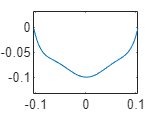


redmap = [1,1,1;1,0,0];                         %相当与调色板,设置图像颜色
colormap(redmap);                               %染色

image(mesh.ys,mesh.zs,flipud(hull),'AlphaData',0.5);
axis([-0.12 0.12 -0.13 0]);                     %坐标界面调节
axis equal;


boat.hull = computeHull(mesh,boat);             %对boat下的hull对象赋值,只包含1，0的逻辑矩阵

y =    -0.1040   -0.1030   -0.1020   -0.1010   -0.1000   -0.0990   -0.0980   -0.0970   -0.0960   -0.0950   -0.0940   -0.0930   -0.0920   -0.0910   -0.0900   -0.0890   -0.0880   -0.0870   -0.0860   -0.0850   -0.0840   -0.0830   -0.0820   -0.0810   -0.0800   -0.0790   -0.0780   -0.0770   -0.0760   -0.0750   -0.0740   -0.0730   -0.0720   -0.0710   -0.0700   -0.0690   -0.0680   -0.0670   -0.0660   -0.0650   -0.0640   -0.0630   -0.0620   -0.0610   -0.0600   -0.0590   -0.0580   -0.0570   -0.0560   -0.0550


p1 = 153300

p2 = -627.7000

p3 = -2172

p4 = 9.7880

p5 = 14.6200

p6 = -0.0244

p7 = -0.0996

z =    -0.0024   -0.0068   -0.0109   -0.0148   -0.0184   -0.0218   -0.0249   -0.0278   -0.0306   -0.0331   -0.0355   -0.0377   -0.0398   -0.0417   -0.0435   -0.0451   -0.0467   -0.0481   -0.0495   -0.0507   -0.0519   -0.0530   -0.0540   -0.0549   -0.0558   -0.0567   -0.0575   -0.0582   -0.0589   -0.0596   -0.0603   -0.0609   -0.0615   -0.0621   -0.0627   -0.0633   -0.0638   -0.0644   -0.0649   -0.0654   -0.0660   -0.0665   -0.0671   -0.0676   -0.0681   -0.0687   -0.0693   -0.0698   -0.0704   -0.0710


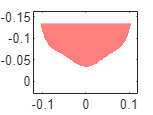

plotMatrix(boat.hull,mesh,redmap);

axis equal;
boat.num_cells = matrixSum(boat.hull)           %boat.hull为布尔矩阵，通过矩阵求和后得到微分方块数量

boat = 包含以下字段的 struct :
            L: 0.4560
            W: 0.2080
           HB: 0.1040
            D: 0.1340
         mass: 3.5000
         hull: [135×209 logical]
    num_cells: 14666


areahull = boat.num_cells *mesh.dA              %计算截面面积

areahull = 0.0145

volumehull = areahull * boat.L                  %获取体积（截面面积*船体长度）

volumehull = 0.0066

masshull = volumehull * density_water           %排水质量

masshull = 6.7716

### 这里通过添加配重调节重心

boat.mass_per_cell = boat.mass / boat.num_cells;    

masses = hull * boat.mass_per_cell;             %每个微分方块的质量
matrixSum(masses)                               %船体总质量

ans = 3.5000

COM_weight2 = centerOfMass2(masses, mesh)       %未加配重时重心

COM_weight2 =    -0.0004   -0.0388


[abc,index_z] = min(z);                         %船体最低点值abc，最低点下标index_z
position_02 = [y(index_z),abc]                  %位置坐标 

position_02 =     0.0010   -0.0996


masses = addMass2(0.5,position_02,masses,mesh); %演示添加配重
matrixSum(masses)

ans = 4.0000

COM_weight2 = centerOfMass2(masses, mesh)       %重心位置

COM_weight2 =    -0.0002   -0.0464


## 通过二分法，循环判断，收敛空载水线：

- 水平条件下，无倾角

- 这里水线值，需要大家尝试得到

d = -0.06686;                                   %预设初始空载水线高度
d_gap= 0.1;                                     %二分步长
theta = 0;                                      %水平状态
i=1;
while 1
     y = mesh.ys;
     z = tand(theta) * y + d;
    
    water = mesh.zgrid <z;                      %水线下的水体矩阵

    sub_region = boat.hull&water;               %矩阵交集，求取排水体积
    force=sub_region.*density_water*0.00001;    %计算单个微分方块的力
   
    lift= matrixSum(force);                     %整体浮力
    up_force=lift-boat.mass*9.8;                %浮力剩余值

    if up_force<0                           
        d=d+d_gap/i;                        
    elseif up_force>0
        d=d-d_gap/i;
    else 
        break;
    end

    if up_force>-0.5&&up_force<0.5              %判断阈值，水线收敛
       break;
    end
    i=i*2;                                      %缩短步长   
end   
lift

lift = 34.6963

boat.mass*9.8

ans = 34.3000

### 确定浮心位置

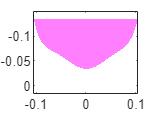

%倾转0度时
theta = 0;
water=computeWater(d,theta,mesh);                %根据之前确定的水线，确定水体矩阵  
sub_region = boat.hull&water;                    %求船体，确定沉浸在水体中的船体
              
purplemap = [1,1,1; 1,0,1];
plotMatrix(water,mesh,purplemap);                %水体图像

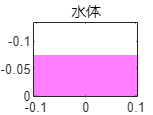

title('水体')
plotMatrix(sub_region,mesh,purplemap);           %沉浸于水体中的船体

title('沉浸水中的船体')
axis equal;
COB = centerOfMass2(sub_region,mesh);            %获取浮心位置

%water = computeWater(d,theta,mesh);
%axis([-0.13 0.13 -0.15 0]);
%plotMatrix(water,mesh,bluemap);

### 当翻转角大于90度时，将boat.hull向上翻转

%倾转135度时
theta = 135;

d = water_line(mesh,theta,boat)

d = -0.1430

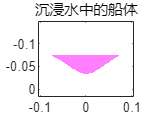

water=computeWater(d,theta,mesh);                %根据之前确定的水线，确定水体矩阵  
plotMatrix(water,mesh,purplemap);                %此时水体的图像

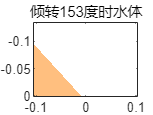

title('倾转153度时水体')
sub_region = flipud(boat.hull)&water;            %求船体，确定沉浸在水体中的船体
%flipud()上下翻转矩阵
%fliplr(）左右翻转矩阵
cus_map = [1,1,1; 1,0.5,0];
plotMatrix(sub_region,mesh,cus_map);             %沉浸于水体中的船体

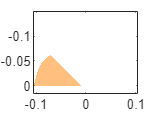

axis equal;

COB = centerOfMass2(sub_region,mesh)            %获取浮心位置

COB =    -0.0646   -0.1122


### 得到浮心，重心后计算扶正力矩

%角度为零：
COM_weight2,COB

COM_weight2 =    -0.0002   -0.0464


COB =    -0.0646   -0.1122


torq = torque(COM_weight2,COB,lift,theta)

torq = -2.2582

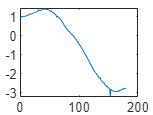



for theta = 1:1:180                             %重复上述过程，作出扶正力矩图
    d =  water_line(mesh,theta,boat);
    water=computeWater(d,theta,mesh);
    if theta>90 && theta<=180
        sub_region = flipud(boat.hull)&water;
    elseif  theta<=90 && theta>=0
        sub_region = boat.hull&water;
    end
    COB = centerOfMass2(sub_region,mesh);
    torq_pic(theta) = torque(COM_weight2,COB,lift,theta);
    theta_pic(theta) = theta;
end

plot(theta_pic,torq_pic);                          %扶正力矩曲线

# 这里图像显示90度左右力矩大小翻转，说明并未达到船体设计要求，需要大家结合实际进行修改

# 三维船体：(这里暂时只给出了浮心、重心的计算)

## 总体思路：

- 将船体切片，得到船体截面

- 计算单一截面上浮心位置，得到三维浮心分布

- 合成浮心得到最终浮心位置

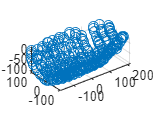

%%%
clear 
clc

Coord=load("point.m");%导入坐标点数据


x_axis=Coord(:,1);%x,y,z轴
y_axis=Coord(:,2);
z_axis=Coord(:,3);


%绘制散点图
figure,scatter3(x_axis,y_axis,z_axis)
axis equal%坐标轴比例


%绘制拟合曲面
figure
p =z_axis>100;
z_axis(p)=NaN;
[X,Y,Z]=griddata(x_axis,y_axis,z_axis,linspace(min(x_axis),max(x_axis))',linspace(min(y_axis),max(y_axis)),'v4');%插值

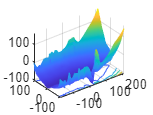

figure,meshc(X,Y,Z);                                                            %三维曲面+等高线
set(gca,'DataAspectRatio',[1 1 1])                                              %设置坐标轴比例
hidden off


mesh.xs =x_axis*0.001;
mesh.ys =y_axis*0.001;
mesh.zs =z_axis*0.001;

[mesh.xgrid,mesh.ygrid,mesh.zgrid]=meshgrid(mesh.xs,mesh.ys,mesh.zs);

cube.density=1;     

masses_3D = cube.density * ones(size(mesh.xgrid));
COM3D=COMof3D(masses_3D,mesh);

    waterline = -0.06;
    dy = 0.01;
    dz = 0.01; 
        
    boat.W = max(mesh.ys)-min(mesh.ys);        
    boat.HB = boat.W / 2;  % half breadth in 
    boat.D = max(mesh.zs)-min(mesh.zs); 



% 按需对x轴的值进行四舍五入
roundedX = round(x_axis);

% 获取四舍五入后的x轴上的唯一值
uniqueX = unique(roundedX);

% 计算唯一值的数量
numUniqueX = length(uniqueX);

% 初始化一个cell数组来存储y和z的值
yzCell = cell(numUniqueX, 1);

% 遍历x轴上的每个唯一值
for i = 1:numUniqueX
    % 获取当前x值对应的索引
    currentIndexes = roundedX == uniqueX(i);
    
    % 提取与当前x值对应的y和z值，并将它们存储在一个Nx2的矩阵中
    % 其中N是当前x值出现的次数
    yzMatrix = [y_axis(currentIndexes), z_axis(currentIndexes)];
    
    % 将当前x值对应的yz矩阵存储在cell数组中
    yzCell{i} = yzMatrix*0.001;
end
    clear Coord,clear x_axis,clear z_axis,clear y_axis;     %咱内存不够了
    clear mesh.ys,clear mesh.zs,clear mesh.xs;


## 跟二维计算类似：

处理数据，根据x值进行分类：


    % 遍历yzCell中的每个元素
for i = 1:length(yzCell)
    % 从当前cell中提取y和z值的矩阵
    %clear mesh;
    yzMatrix = yzCell{i};
    
    % 提取y值和z值
    yValues = yzMatrix(:, 1);
    zValues = yzMatrix(:, 2);
    
    mesh.ys = yValues;
    mesh.zs = zValues;
    
    mesh.ys_face = min(mesh.ys) :dy: max(mesh.ys );
    mesh.zs_face = min(mesh.zs ):dy: max(mesh.zs );

 

    [mesh.ygrid,mesh.zgrid]=meshgrid(mesh.ys_face,mesh.zs_face);
    
    total_area = boat.W * boat.D;       % m^2截面总面积

    mesh.dA = total_area / numel(mesh.ygrid);
    
    y = mesh.ys_face;

       p1 =   1.533e+05 ;
       p2 =      -627.7 ;
       p3 =       -2172 ;
       p4 =       9.788 ;
       p5 =       14.62 ;
       p6 =    -0.02439 ;
       p7 =    -0.09962 ;
    z = p1*y.^6 + p2*y.^5 + p3*y.^4 + p4*y.^3 + p5*y.^2 + p6*y + p7;

    hull = mesh.zgrid > z;
    boat.hull = hull;                                %对boat下的hull对象赋值,只包含1，0的逻辑矩阵
    boat.num_cells = matrixSum(boat.hull);           %boat.hull为布尔矩阵，通过矩阵求和后得到微分方块数量
    areahull = boat.num_cells *mesh.dA;              %计算截面面积
  

    %倾转0度时
    theta = 0;
                 
    
    z = tand(theta) .* y + waterline;
    water = mesh.zgrid < z;                          %根据之前确定的水线，确定水体矩阵  

    sub_region = boat.hull&water;                    %求船体，确定沉浸在水体中的船体
    COB_3D(i,:) = centerOfMass2(sub_region,mesh); 
    COB_3D(find(isnan(COB_3D))) = 0;                 %船型曲线因素，会出现一些截面没有浸入水中，矩阵数值会出现NaN,这里做近似处理,将空值写0；
end
    clear mesh;
    
    mesh.ys = COB_3D(:,1);
    mesh.zs = COB_3D(:,2);
    mesh.xs = uniqueX*0.001;
    [mesh.xgrid,mesh.ygrid,mesh.zgrid]=meshgrid(mesh.xs,mesh.ys,mesh.zs);

    cube.density=1;

    masses_3D = cube.density * ones(size(mesh.xgrid));
    COB_of_3D=COMof3D(masses_3D,mesh);
    COM3D,COB_of_3D

COM3D =     0.0044   -0.0040   -0.0438


COB_of_3D =     0.0120   -0.0000   -0.0684



toc;

历时 4.859301 秒。


disp(['运行时间：',num2str(toc),'s']);

运行时间：4.8683s


# 函数定义：

function plotMatrix(A,mesh,cmap)
    colormap(cmap);
    image(mesh.ys,mesh.zs,flipud(A),'AlphaData',0.5);
end

function M = matrixSum(A)
    M = sum(A(:));
end

function water = computeWater(d,theta,mesh)
y = mesh.ys;
z = tand(theta) .* y + d;
    
water = mesh.zgrid < z;
end

### 计算扶正力矩

function torq = torque(COM,COB,lift,theta)
    L = cosd(theta)*sqrt((COB(1)-COM(1))^2+(COB(2)-COM(2))^2);
    torq = L*lift;
end

## 二分法确定水线

- 同上述空载水线同理

function D_line = water_line(mesh,theta,boat)   
     num = 1;
     i=1;
     d = -0.02;
     d_gap = 0.07;
     density_water = 1025; 
while num<100
   
     y = mesh.ys;
     z = tand(theta) * y + d;
    
     water = mesh.zgrid <z;                      %水线下的水体矩阵
    if theta>90 && theta<=180
        sub_region = flipud(boat.hull)&water;   %矩阵交集，求取排水体积
    elseif  theta<=90 && theta>=0
        sub_region = boat.hull&water;
    end

    force=sub_region.*density_water*0.00001;    %计算单个微分方块的力
   
    lift= matrixSum(force);                     %整体浮力
    up_force=lift-boat.mass*9.8;                %浮力剩余值

    if up_force<0                           
        d=d+d_gap/i;                        
    elseif up_force>0
        d=d-d_gap/i;
    else 
        break;
    end

    if up_force>-0.5&&up_force<0.5              %判断阈值，水线收敛
       break;
    end
    i=i*2;                                      %缩短步长
    num=num+1;
end  
    D_line = d;
    
end

## ***Author :***** 陈思念**